# Figure S9B, S9D

#### **L**oad data

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A076_data.mat'],'S','settings','allIF');

conditions = settings.conditions;


framesPerHr = 60/12;
 frameDrugAdded =0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
      if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .2 & ...
                nanmean(dat.apcNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .02;
      end
    end
   
    S(i).apcExpressGate = apcExpressGate;
  
end

S9B right

conds=[1:10];
POI_align = 1;
ally = [];
groups = [];

figure ('units','inches','position',[0 0 3 3])
 g1length = zeros(10,1);
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = ~isnan(data.POI(:,1)) & ~isnan(data.POI(:,3))& ...
      data.apcExpressGate & data.goodCdk;

sum(inds)

yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
   yvals = yvals( yvals > 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];

    mean(yvals);
    g1length(i,:) = mean(yvals);

    clear yvals;
end

ans = 624

ans = 926

ans = 1202

ans = 1568

ans = 1663

ans = 1686

ans = 1690

ans = 2205

ans = 1954

ans = 1648

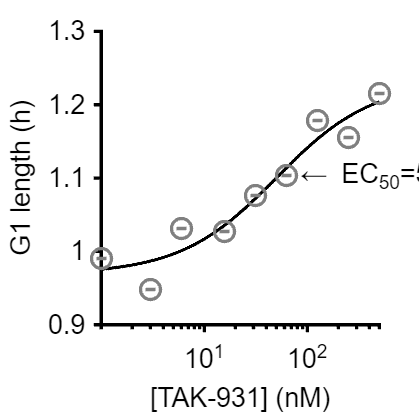


dose = [500 ;250 ;125; 62.5; 31.25; 15.6 ;6 ;3; 1; 0];



doseResponse(dose,g1length,1);
box off
 ylim([0.9 1.3])

xticks([0,10,100])
xlabel('[TAK-931] (nM)');

ylabel('G1 length (h)');

% print_pdf('rpe1_g1_dose.pdf')

S9B left

conds=[1:10];
colors = [.6 .8 .1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
cols = [.6 .8 .1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
POI_align = 3;
ally1 = [];
ally2 = [];

groups = [];
groups2=[];
clear yvals2;
clear yvals1;

timeGate = [0 20];
figure ('color','white')

cdk_at_POI = NaN*ones(length(dat.POI(:,3)),length(conds));
apc_s = NaN*ones(length(dat.POI(:,3)),length(conds));

for i = 1:length(conds)

    crlAct = S(conds(i)).POI(:,3);
    apcinact = S(conds(i)).POI(:,2);
    mitosis = S(conds(i)).POI(:,1);
    cdk2 = S(conds(i)).cdk;
    c = conds(i);
    data = S(c);

    inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,2)) &  ...
        data.POI_realtime(:,1) <= timeGate(2) & data.POI_realtime(:,1) >= timeGate(1) &...
        data.apcExpressGate  & data.goodCdk & (data.POI_realtime(:,3)-data.POI_realtime(:,2)>0);

    sum(inds)
    crlAct = crlAct(inds,:);

    apcinact = apcinact(inds,:);

    mitosis = mitosis(inds,:);
    cdk2 = smoothdata(cdk2(inds,:),2,'sgolay',2);




    for n = 1:size(crlAct,1)

        if ~isnan((crlAct(n,1)-apcinact(n,1))/5) & ~isnan (double(cdk2(n,crlAct(n))))
            yvals1(n,1) = ((crlAct(n,1)-apcinact(n,1))/5);
            yvals2(n,1) = double(cdk2(n,crlAct(n)));

        end


        cdk_at_POI(n,i) = cdk2(n,crlAct(n));
        apc_s(n,i)= data.POI_realtime(n,3)-data.POI_realtime(n,2);
    end
    meanapc_s(i) = mean(yvals1);
  
    ally1 = [ally1; yvals1];

    groups = [groups; repmat(i,size(yvals1))];

    ally2 = [ally2; yvals2];
    groups2 = [groups2; repmat(i,size(yvals2))];

    cdk_threshold(i,1) = nanmean(cdk_at_POI(:,i));

    cdk_sd(i) = nanstd(cdk_at_POI(:,i));
    clear yvals1;
    clear yvals2;

end

ans = 591

ans = 876

ans = 1145

ans = 1497

ans = 1563

ans = 1553

ans = 1498

ans = 1966

ans = 1708

ans = 1382

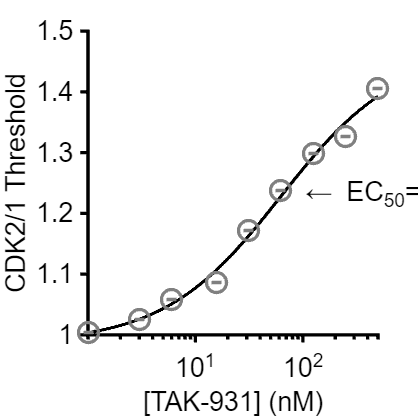

sem=cdk_sd./(sqrt(sum(~isnan(cdk_threshold),1)));

tak_dose = [500; 250; 125; 62.5;31.25;15.6;6;3;1;0];


figure ('units','inches','position',[0 0 6 6])
doseResponse(dose,cdk_threshold,1);
xticks([0,10,100])
ylim([1 1.5])
yticks(1: .1 : 1.5)
xlabel '[TAK-931] (nM)'
ylabel 'CDK2/1 Threshold'
box off 
% print_pdf(['Fig_S9B_left.pdf'])
hold off 

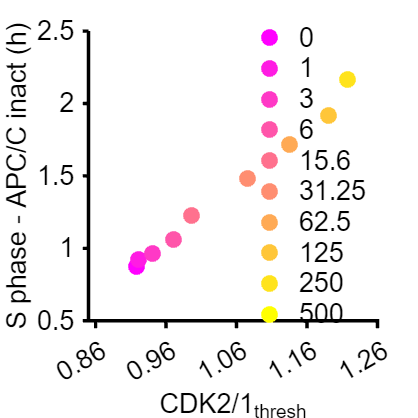




%S9D


figure ('units','inches','position',[0 0 6 6])
hold on
gscatter(cdk_threshold,meanapc_s,tak_dose,spring(10),'.',30);
axis square

xlim([.85 1.26])
ylim([.5  2.5])
xticks([0.86:0.1:1.36])
yticks(0: .5 : 2.5)
set(gca,'box','off','fontsize',16,'linewidth',2)
ylabel([ 'S phase - APC/C inact (h)'],'FontSize',16)
xlabel ('CDK2/1_{thresh}','FontSize',16)
legend('box','off','FontSize',16)

hold off


% print_pdf(['Fig_S9D'])